addpath('./functions');
addpath('./data');

dataset = [];
classes = [];
for i=1:1
    str = ['data\cifar-10-batches-mat\data_batch_', num2str(i),'.mat'];
    load(str)
    dataset = [dataset; data];
    classes = [classes; labels];

end

load('data\cifar-10-batches-mat\test_batch.mat');

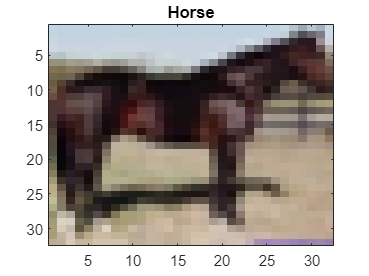

[permutedImageData, categoricalLabels] = permute_dataset(dataset, classes);
labels_names = ["Airplane", ...
                "Automobile", ...
                "Bird", ...
                "Cat", ...
                "Deer", ...
                "Dog", ...
                "Frog", ...
                "Horse", ...
                "Ship", ...
                "Truck", ...
                ];

labels_numbers = ["0", ...
                  "1", ...
                  "2", ...
                  "3", ...
                  "4", ...
                  "5", ...
                  "6", ...
                  "7", ...
                  "8", ...
                  "9", ...
                  ];

label2name = dictionary(labels_numbers, labels_names);
idx = randi(size(permutedImageData,4));

imagesc(permutedImageData(:,:,:,idx))
title(label2name(categoricalLabels(idx)))

layers = basic_cnn_classifier()

layers =   13×1 Layer array with layers:

     1   ''   Image Input             32×32×3 images with 'zerocenter' normalization
     2   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                    ReLU
     4   ''   2-D Convolution         32 3×3 convolutions with stride [1  1] and padding 'same'
     5   ''   ReLU                    ReLU
     6   ''   2-D Max Pooling         2×2 max pooling with stride [1  1] and padding [0  0  0  0]
     7   ''   ReLU                    ReLU
     8   ''   2-D Max Pooling         2×2 max pooling with stride [1  1] and padding [0  0  0  0]
     9   ''   Fully Connected         128 fully connected layer
    10   ''   ReLU                    ReLU
    11   ''   Fully Connected         10 fully connected layer
    12   ''   Softmax                 softmax
    13   ''   Classification Output   crossentropyex

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       14.06% |       2.2987 |          0.0100 |
|       1 |          50 |       00:00:05 |       38.28% |       1.8415 |          0.0100 |
|       2 |         100 |       00:00:08 |       41.41% |       1.6650 |          0.0100 |
|       2 |         150 |       00:00:11 |       40.62% |       1.5485 |          0.0100 |
|       3 |         200 |       00:00:14 |       52.34% |       1.2999 |          0.0100 |
|       4 |         250 |       00:00:17 |       50.78% |       1.3880 |          0.0100 |
|       4 |         300 |       00:00:34 |       57

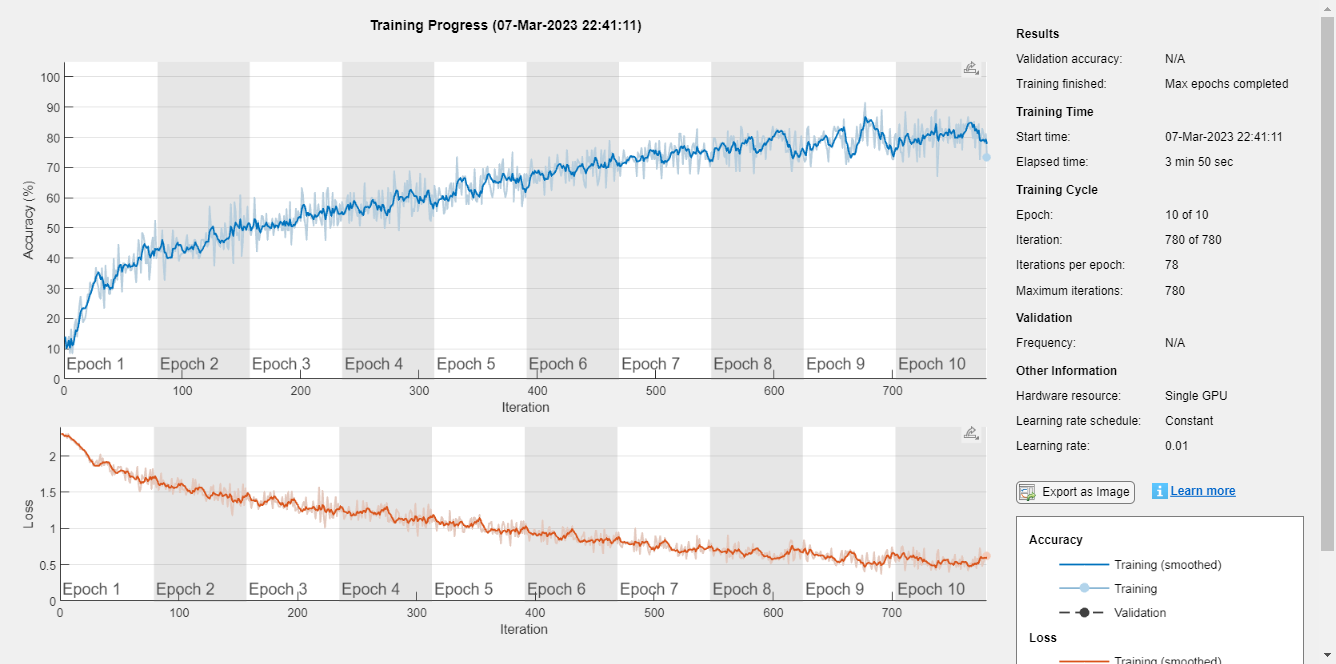

options = trainingOptions('sgdm', "ExecutionEnvironment","gpu",Plots="training-progress", MaxEpochs=10);
net = trainNetwork(permutedImageData,categoricalLabels, layers, options);

[testData, testLabels] = permute_dataset(data,labels);

preds = net.classify(testData);
tp = nnz(preds == testLabels);
accuracy = tp / length(testLabels);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 54.03%


test_size = 0.2

test_size = 0.2000

% normalizedData = normalize(permutedImageData);
[X_train, X_val, Y_train, Y_val] = train_test_split(permutedImageData, categoricalLabels, test_size);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        9.38% |        9.40% |       2.3089 |       3.7891 |          0.0010 |
|       1 |          50 |       00:00:06 |       28.12% |       30.45% |       1.9277 |       1.9766 |          0.0010 |
|       1 |         100 |       00:00:19 |       37.50% |       38.55% |       1.5988 |       1.7481 |          0.0010 |
|       2 |         150 |       00:00:36 |       56.25% |       45.65% |       1.3683 |       1.5694 |          0.

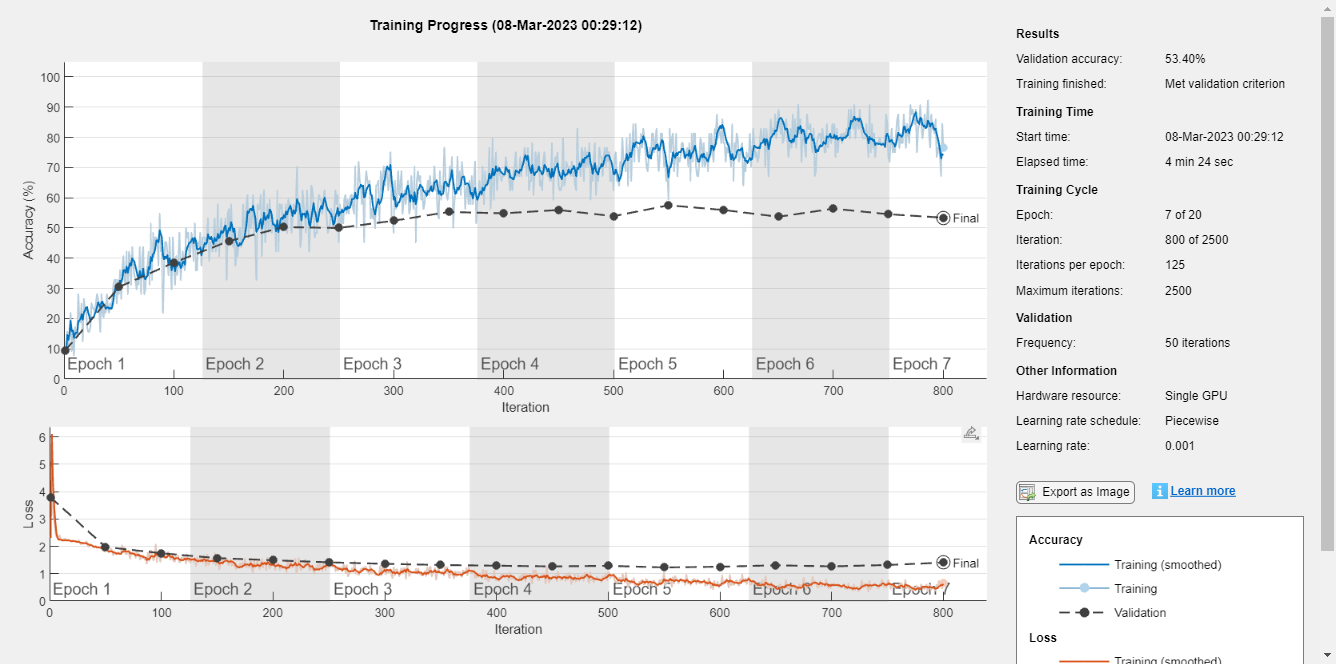

layers = basic_cnn_classifier();
options = trainingOptions("adam", "ExecutionEnvironment","gpu",ValidationData={X_val, Y_val},Plots="training-progress", MaxEpochs=20, ValidationPatience=5, LearnRateSchedule="piecewise", MiniBatchSize=64);
net = trainNetwork(X_train ,Y_train, layers, options);

preds = net.classify(testData);
tp = nnz(preds == testLabels);
accuracy = tp / length(testLabels);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 54.25%
